# 2023-2024-1 数学软件期中考试题

班级：                       姓名：                     学号：                     

**考试时间：110+5分钟    考试形式：闭卷      总分：100**

- 请先填写上面的**班级姓名学号**。**闭卷**，只可查看MATLAB的help。

- 在结束前5分钟完成答题，将你的答卷导出为pdf 文件并提交。

- 你提交的**文件名应改为你的班级姓名.pdf**，如“信计1221张三.pdf”。

**一. 填空题：(4分x10=40分)**

(1) 下列的**哪些**字符串，可以作为MATLAB的变量名（           ）。

A. gdou2023      B. gdou.2023       C. gdou-2023        D.  gdou_2023

(2)  在MATLAB中，**分别**用冒号表达式和函数linspace()建立一个起点为10，终点为5，步长为 -0.5 的数组x.

x=10:-0.5:5;
linspace(10,5,11)

ans =    10.0000    9.5000    9.0000    8.5000    8.0000    7.5000    7.0000    6.5000    6.0000    5.5000    5.0000


(3)  在MATLAB中，**不直接输入**，生成矩阵 $A=\left(\begin{array}{cccc}1&2&3&4\\5&6&7&8\end{array}\right)$，再用一条命令将其各列分别加上0.1, 0.2, 0.3, 0.4.

% 生成矩阵 A（假设 A 为 4 行 4 列）
A = reshape(1:8, 2, 4)% 示例矩阵，可替换为其他生成方法

A =      1     3     5     7
     2     4     6     8



% 定义需要加到各列的行向量
offset = [0.1, 0.2, 0.3, 0.4]

offset =     0.1000    0.2000    0.3000    0.4000



% 使用矩阵加法
A = A + offset

A =     1.1000    3.2000    5.3000    7.4000
    2.1000    4.2000    6.3000    8.4000


(4) 以下代码运行时将出错，其错误原因是：（                           ）  

(5) 在MATLAB中计算下列表达式的值：  

(a) $\sin\frac{\pi}{\sqrt{3}}$            (b) $e^{2\ln 3}$

a=sin(pi/sqrt(3))
b=exp(2 * log(3))

(6) 用MATLAB命令判断下列线性方程组 $\left(\begin{array}{ccc} 3&7&9\\7&1&6\\9&6&4\end{array}\right)\left(\begin{array}{c}x_1\\x_2\\x_3\end{array}\right)=\left(\begin{array}{c}16\\23\\9\end{array}\right)$是否有解，若有解则求出其解。

A=[3 7 9;

a = 0.9706

    7 1 6;

b = 9.0000

    9 6 4]
b=[16;
    23;
    9]
if rank(A)==rank([A b])

A =      3     7     9
     7     1     6
     9     6     4


   x=A\b
end

b =     16
    23
     9


(7) 已知矩阵 $M=\left(\begin{array}{ccc} 3&7&9\\7&1&6\\9&6&4\end{array}\right)$，求它的各行元素之和、行列式、特征值. 

A=[3 7 9;
    7 1 6;
    9 6 4]

x =     1.0000
   -2.0000
    3.0000


row=sum(A,2)
lie=sum(A,1)
det(A)
eig(A)

A =      3     7     9
     7     1     6
     9     6     4


(8) 建立符号函数 $f(x) = xe^{\frac x2}$，并做下列操作：

      (a) 求二阶导； (b) 求 $\displaystyle\int_0^2 f(x) dx.$

syms x

row =     19
    14
    19


f = x*exp(x/2)

lie =     19    14    19


f_prime = diff(f, x)

ans = 383

f_double_prime = diff(f_prime, x)

ans =    -5.9085
   -3.6845
   17.5930


int(f,x,0,2)

(9) 在MATLAB中，求方程 $e^{-x^2}+\sin3x=0$ 在 x0= 2 附近的根。

f=@(x) exp(-x.^2)+sin(3*x)
x0=2;

$$f = x\,{\mathrm{e}}^{x/2}$$

fzero(f,x0)

$$f\_prime = {\mathrm{e}}^{x/2}+\frac{x\,{\mathrm{e}}^{x/2}}{2}$$

(10) 在MATLAB中，求函数 $y=e^{-x^2}+\sin3x$在(1, 3)上的极小值点及极小值。

f=@(x) exp(-x.^2)+sin(3*x)

$$f\_double\_prime = {\mathrm{e}}^{x/2}+\frac{x\,{\mathrm{e}}^{x/2}}{4}$$

[xmin,ymin]=fminbnd(f,1,3)

$$ans = 4$$

**二. 程序设计题，以下9个题任选5个完成（6、9题至少选1个），每题12分。**

1. 分别用循环和数组运算求级数和 $S=\sum\limits_{n=1}^{100}\frac1{(n+1)(4n-3)}$，并用 fprintf 输出小数点后15位小数。

% 使用循环计算级数和
S_loop = 0;

f = 包含以下值的 function_handle :
    @(x)exp(-x.^2)+sin(3*x)


for n = 1:100
    S_loop = S_loop + 1 / ((n + 1) * (4 * n - 3));

ans = 2.0902

end

% 输出结果

f = 包含以下值的 function_handle :
    @(x)exp(-x.^2)+sin(3*x)


fprintf('使用循环计算的级数和 S = %.15f', S_loop);

xmin = 1.5984

ymin = -0.9189

% 以下用数组运算求级数和

n = 1:100; % 创建一个包含 1 到 100 的数组
S_array = sum(1 ./ ((n + 1) .* (4 * n - 3))); % 计算级数和

2. 已知一个函数 $y=f(x)$上的若干个采样点的取值如下表所示：

        
$$\begin{array}{cccccccc}x\; &-0.5\;&-0.2\;&0.1\;&0.4\;&0.7\;&1.0\;&1.3\;&1.6\\\hline y\; &2.5\; &2.9\; &3.1\; &3.3\; &3.1\; &3.1\; &3.2\;&3.4\end{array}$$


用3次函数作拟合，求拟合函数的系数向量p。并在同一坐标系中用红色圆圈表现采样点，用蓝色实线表现拟合函数(取步长为0.02)，给出图例。在下面的单元中编写代码并运行。

x=[-0.5,-0.2,0.1,0.4,0.7,1.0,1.3,1.6]

使用循环计算的级数和 S = 0.661835181273193

y=[2.5, 2.9 ,3.1,3.3,3.1,3.1,3.2,3.4]
p=polyfit(x,y,3)
x_fit=min(x):0.02:max(x)
y_fit = polyval(p, x_fit);
plot(x,y)
plot(x_fit,y_fit)

3. 对符号函数 $y=e^{-x^2}$做最高次为4次和6次的Taylor展开，并在 $x\in[-1, 1]$上绘制该函数及其Taylor展开的图形，坐标轴上采用等长刻度，并添加图例。

syms x
f= exp(-(x^2))
fplot(f,[-1,1])
hold on
a1=taylor(f,x,"Order",5)
fplot(a1,[-1,1])
hold on
a2=taylor(f,x,"Order",7)
fplot(a2,[-1,1])
grid on
axis equal

$$f = {\mathrm{e}}^{-x^{2}}$$

4.  在同一图形窗口中，分左右子图，分别绘制函数 $e^{-x^2-y^2}$ 在区域 $x,y\in[-2,2]$上的图形和在 $x^2+y^2\leq4$上的图形。自行加上合适的标题。

subplot(1,2,1)
[x,y]=meshgrid(-2:0.1:2,-2:0.1:2)
z = exp(-x.^2 - y.^2)

$$a1 = \frac{x^{4}}{2}-x^{2}+1$$

mesh(x,y,z)
axis equal;
subplot(1,2,2)

$$a2 = -\frac{x^{6}}{6}+\frac{x^{4}}{2}-x^{2}+1$$

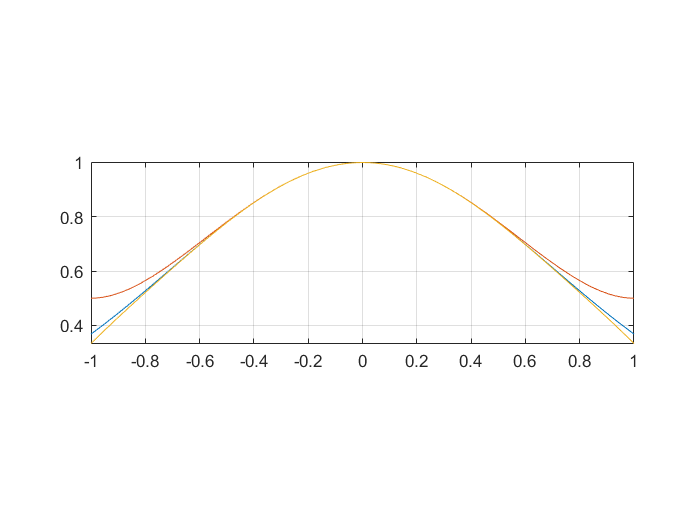

threat=linspace(0,2*pi,100)
r=2
x=r*cos(threat)

y=r*sin(threat)
plot(x,y)
axis equal;

5. 某公司5个部门，其营收和人数如下表所示：


$$\begin{array}{cccccc}部门 &A& B  &C &D& E\\\hline 营收(百万元)& 28.2 &12.7  & 30.6 & 10.8  & 18.5\\\hline 人数 & 18 & 8&22&11&15 \end{array}$$


请在同一图形窗口中，分左右子图，左子图中用饼图表现各部门营收，右子图中用条形图表现人均营收。各加上标题。

categories={'a','b','c','d','e'}

x =    -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000
   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000
   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -

y =    -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000
   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000   -1.9000
   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -

subplot(1,2,1)

z =     0.0003    0.0005    0.0007    0.0010    0.0014    0.0019    0.0026    0.0034    0.0043    0.0055    0.0067    0.0081    0.0097    0.0112    0.0128    0.0143    0.0156    0.0167    0.0176    0.0181    0.0183    0.0181    0.0176    0.0167    0.0156    0.0143    0.0128    0.0112    0.0097    0.0081    0.0067    0.0055    0.0043    0.0034    0.0026    0.0019    0.0014    0.0010    0.0007    0.0005    0.0003
    0.0005    0.0007    0.0011    0.0015    0.0021    0.0029    0.0038    0.0050    0.0064    0.0081    0.0100    0.0120    0.0143    0.0166    0.0189    0.0211    0.0231    0.0247    0.0260    0.0268    0.0271    0.0268    0.0260    0.0247    0.0231    0.0211    0.0189    0.0166    0.0143    0.0120    0.0100    0.0081    0.0064    0.0050    0.0038    0.0029    0.0021    0.0015    0.0011    0.0007    0.0005
    0.0007    0.0011    0.0015    0.0022    0.0030    0.0041    0.0055    0.0072    0.0093    0.0117    0.0144    0.0174    0.0207    0.0240    0.0273    0.0305    0.0334    

data1=[28.2,12.7,30.6,10.8,18.5]
pie(data1,categories)
title('13dsfsdf')
subplot(1,2,2)

threat =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


data2=[18,8,22,11,15]

r = 2

bar(data2)

x =     2.0000    1.9960    1.9839    1.9639    1.9359    1.9001    1.8567    1.8059    1.7477    1.6825    1.6105    1.5321    1.4475    1.3570    1.2611    1.1601    1.0545    0.9445    0.8308    0.7138    0.5938    0.4715    0.3473    0.2217    0.0952   -0.0317   -0.1585   -0.2846   -0.4096   -0.5329   -0.6541   -0.7727   -0.8881   -1.0000   -1.1078   -1.2112   -1.3097   -1.4029   -1.4905   -1.5721   -1.6474   -1.7160   -1.7777   -1.8322   -1.8794   -1.9190   -1.9509   -1.9749   -1.9909   -1.9990


set(gca,"XTickLabel",categories)

y =          0    0.1268    0.2532    0.3785    0.5023    0.6241    0.7433    0.8596    0.9724    1.0813    1.1858    1.2856    1.3802    1.4692    1.5523    1.6292    1.6995    1.7629    1.8193    1.8683    1.9098    1.9436    1.9696    1.9877    1.9977    1.9997    1.9937    1.9796    1.9576    1.9277    1.8900    1.8447    1.7920    1.7321    1.6651    1.5915    1.5115    1.4254    1.3335    1.2363    1.1341    1.0274    0.9165    0.8019    0.6840    0.5635    0.4406    0.3160    0.1901    0.0635


title('2sfasdsa')

6.  某人在银行存款20万，月利率为0.15%，从第2月初起每月从中取出2000元，则能取多少个月（最后一次可能不足2000）？他总共从银行取了多少钱（精确到小数点后2位）？

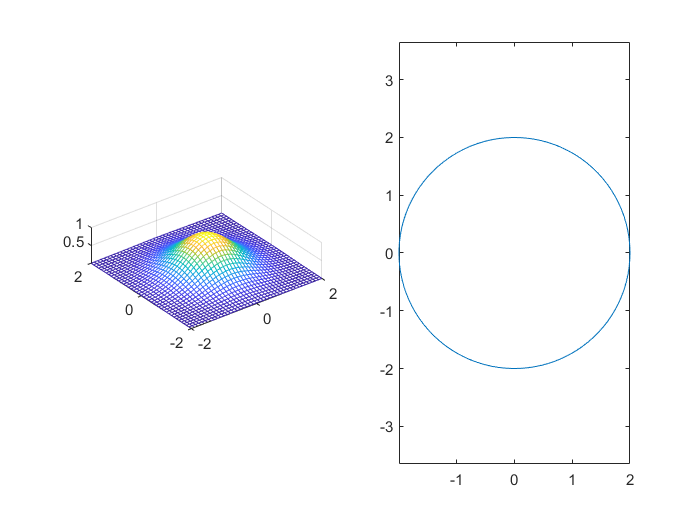

% 定义初始变量

initial_deposit = 200000;  % 初始存款
monthly_interest_rate = 0.0015;  % 月利率
withdrawal_amount = 2000;  % 每月取出金额
months = 0;  % 取款月数
total_withdrawn = 0;  % 总取款金额

categories = 1×5 cell 数组
    {'a'}    {'b'}    {'c'}    {'d'}    {'e'}



% 在第二个月开始取款

data1 =    28.2000   12.7000   30.6000   10.8000   18.5000


current_balance = initial_deposit * (1 + monthly_interest_rate);  % 计算第一个月结束时的余额

% 模拟每个月的取款
while current_balance >= withdrawal_amount

data2 =     18     8    22    11    15


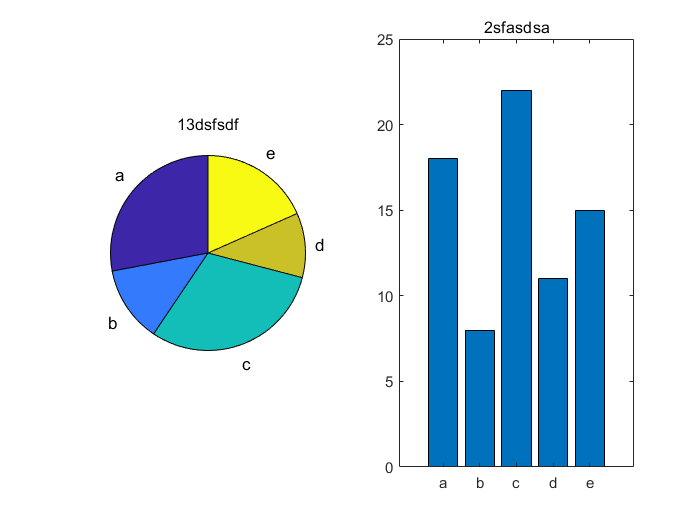

    months = months + 1;
    total_withdrawn = total_withdrawn + withdrawal_amount;
    current_balance = current_balance - withdrawal_amount;

    current_balance = current_balance * (1 + monthly_interest_rate);  % 计算月末余额
end

% 计算最后一个月可能不足2000的取款
if current_balance > 0
    total_withdrawn = total_withdrawn + current_balance;  % 取出剩余金额
    months = months + 1;  % 计入最后一个月
end

% 输出结果
fprintf('总共取款金额: %.2f 元\n', total_withdrawn);
fprintf('取款月数: %d 个月\n', months);


9. 角谷猜想认为：任给一个正整数，若是奇数，就将该数乘3再加上1；若是偶数，就将该数除以2。反复进行上述两种运算，经过有限次运算后，一定能变成1。用MATLAB编程表现这一过程，对输入的正整数，输出从该数变到1的过程中的全体数字。如输入6，则返回[6, 3, 10, 5, 16, 8, 4, 2, 1]。

% 输入正整数
n = 8;

% 初始化输出数组
result = [];

% 进行角谷猜想的计算
while n ~= 1

总共取款金额: 216854.75 元


取款月数: 109 个月


    result+1 = n; % 将当前数添加到结果数组
    if mod(n, 2) == 0
        n = n / 2; % 偶数时，除以2
    else
        n = 3 * n + 1; % 奇数时，乘以3加1
    end
end

% 添加最后的1到结果中
result(end + 1) = 1;

% 输出结果
disp('从该数变到1的过程中的全体数字:')
disp(result)


% 如果需要定义函数的话，请写在以下的代码框中：

'=' 运算符的使用不正确。 '=' 用于为变量赋值，'==' 用于比较值的相等性。